Semicolon suppress output

save command to save the variables to a file,

a = 5;
b = 9;
save datafile.mat
save datafile.mat a

clear command to clear variables

clear

load variables from mat file

load datafile.mat
load datafile.mat a

clear the command window with clc

clc

%constants and functions
pi_ = pi

pi_ = 3.1416

sin_ = sin(90)

sin_ = 0.8940

eig_ = eig(ones(5))

eig_ =    -0.0000
   -0.0000
         0
    0.0000
    5.0000


abs_ = abs(-5)

abs_ = 5

imaginaryNum = 1i^2

imaginaryNum = -1

Matrices and Vectors

x1 = [3, 5, 7] %row vector

x1 =      3     5     7


x2 =      3     5     7


ans = 4

x =      9     2     7


x =      4     2     7


ans = 7

ans = 2

x2 = [3 5 7] %we can use comma or space

xT = [3 5 7]' %single quote transpose

xT =      3
     5
     7



y = [3;5;7] %col vector

y =      3
     5
     7


z = [1 2 3;4 5 6] %2 by 3 matrix

z =      1     2     3
     4     5     6


ans = 1

z(2,3) % element in position 2,3

ans = 6

z(:,3) % allrow,third column

ans =      3
     6


Matrix indexing 

test1 = [3 5 7 12 10] %we can use comma or space

test1 =      3     5     7    12    10



test1(1) %output 3, first element

ans = 3

test1(1) = 9 %change first element

test1 =      9     5     7    12    10



test1(1:2) = [4 2] %change first 2 elements

test1 =      4     2     7    12    10


test1([1 3]) %output 1st and 3rd element 

ans =      4     7



test1(end) %last element

ans = 10

test1(end-1) %next to last element 

ans = 12


test1 = [3 5 7 12 10] 

test1 =      3     5     7    12    10


%logical indexing
test1 > 3 %outputs a mask

ans = 1×5 logical array
   0   1   1   1   1


test1(test1 > 3)

ans =      5     7    12    10


test1(test1 == 3)

ans = 3

test1(test1 ~= 3)

ans =      5     7    12    10


test1(test1 > 3 & test1 < 7)
test1(test1 > 3 | test1 < 7)
test1(test1 ~= 3) = 99 %replace elem neq 3 with 99

test1 =      3    99    99    99    99


p1 = 5:8 % [5 6 7 8] creates a row vector

p1 =      5     6     7     8


p2 = 5:2:8 %start:steps:end, [5 5+2]

p2 =      5     7



p3 = linspace(5,8,3) 

p3 =     5.0000    6.5000    8.0000


%linspace from 5 to 8, evenly spaced 3 elems
%use linspace if you know # elements

Common matrix creation function

randMatrix = rand(5) %random 5 by 5 matrix,

randMatrix =     0.5308    0.4694    0.3112    0.6541    0.2290
    0.7792    0.0119    0.5285    0.6892    0.9133
    0.9340    0.3371    0.1656    0.7482    0.1524
    0.1299    0.1622    0.6020    0.4505    0.8258
    0.5688    0.7943    0.2630    0.0838    0.5383


% elements from 0 to 1

randMatrix2 = rand(2,3)%random 2 by 3 matrix

randMatrix2 =     0.9961    0.4427    0.9619
    0.0782    0.1067    0.0046



zeroMatrix = zeros(2,3) 

zeroMatrix =      0     0     0
     0     0     0


oneMatrix = ones(1,3)

oneMatrix =      1     1     1



rout1 = size(randMatrix2) %outputs shape of matrix

rout1 =      2     3


[rrow,ccol] = size(randMatrix2)

rrow = 2

ccol = 3

Matrix operations

test2 = [1 2 3]

test2 =      1     2     3


out1 = test2 + 3 %add 3 to each elem

out1 =      4     5     6


out2 = test2 * 3

out2 =      3     6     9


out3 = test2 /3

out3 =     0.3333    0.6667    1.0000


out4 = ones(2,3)+ones(2,3) %add 2 matrix same size

out4 =      2     2     2
     2     2     2



out5 = max(test2)

out5 = 3

[xMax,xindex] = max(test2) 

xMax = 3

xindex = 3

%returns max elem and index of the max elem

out6 = round(test2)

out7 =      1     2     3


out7 = sqrt(test2)

out8 =     1.0000    1.4142    1.7321



out8 = test2' * test2 %a dot b, dot product

out8 =      1     2     3
     2     4     6
     3     6     9



out9 = test2 .* test2 %multiply elementwise

out9 =      1     4     9


%same size matrices, multiply at same index

broadcast1 = [1 2; 3 4; 5 6; 7 8].*[1;2;3;4]

broadcast1 =      1     2
     6     8
    15    18
    28    32


%4-by-2 .* 4-by-1
%broadcasts [1;2;3;4] => [1 1;2 2;3 3;4 4]

size([1 2; 3 4; 5 6; 7 8])

ans =      4     2


size([1;2;3;4])

ans =      4     1


Plotting

xaxis = 1:12

xaxis =      1     2     3     4     5     6     7     8     9    10    11    12


yaxis = rand(1,12)

yaxis =     0.4357    0.3111    0.9234    0.4302    0.1848    0.9049    0.9797    0.4389    0.1111    0.2581    0.4087    0.5949


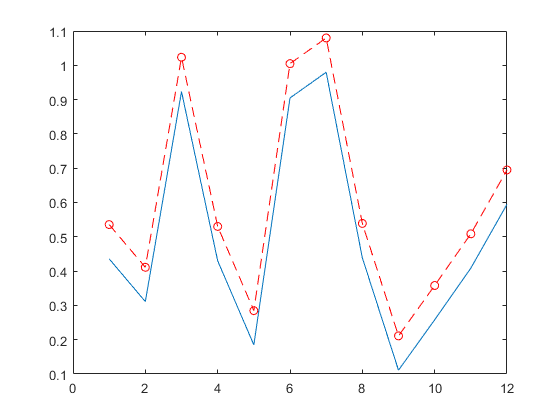

plot(xaxis,yaxis)
hold on %plots both graph on top instead of separate plots
plot(xaxis,yaxis+0.1,"r--o") %r for red, -- with o as marker
hold off

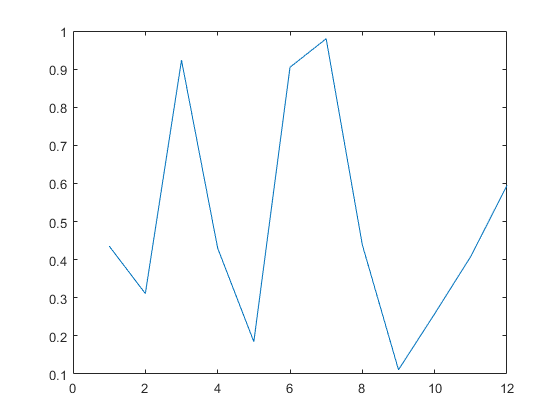

plot(yaxis) %x-axis auto ranges from 1 to size of yaxis